# KCA with threshold testing

clear all
load(['colonyIDs.mat']);
load('KCA_datamatrix_withStateAssignments.mat');

% %Gata2 fitting and Q matrix calculation
clear fd sd pdf_nbinommixture x mixingPrct

x=KCA.gata2(KCA.gata1<100);

kp1=[2 0.0721 11.239 0.10975];  %Derived from Distribution Fitter
pdf_nbinommixture = @(x,p) ...
    p*nbinpdf(x,kp1(1),kp1(2)) + (1-p)*nbinpdf(x,kp1(3),kp1(4));

firstcomp = @(x,p) ...
    p*nbinpdf(x,kp1(1),kp1(2));
secondcomp= @(x,p,c,d) ...
    (1-p)*nbinpdf(x,kp1(3),kp1(4));

p0=[0.6];
options = statset('MaxIter',10000, 'MaxFunEvals',100000);
lb = [0];
ub = [1];
[mixingPrct, pci2] = mle(x, 'pdf',pdf_nbinommixture, 'start',p0, ...
    'lower',lb, 'upper',ub, 'options',options)
G2params=[mixingPrct kp1];

figure(1)

histogram(x,'Normalization','pdf')
hold on
xgrid = linspace(0,900,900);
pdfgrid = pdf_nbinommixture(1:900,mixingPrct(1));
g2fd= firstcomp(1:900,mixingPrct(1));
g2sd= secondcomp(1:900,mixingPrct(1));
plot(xgrid,pdfgrid,'-')
hold on
plot(xgrid,g2fd,'.')
hold on
plot(xgrid,g2sd,'.')
hold off
xlabel('x')
ylabel('Probability Density')

G2Qmat(1,1) = sum( (g2fd ./ (g2fd + g2sd)) .* (g2fd ./ mixingPrct) );
G2Qmat(2,1) = sum( (g2sd ./ (g2fd + g2sd)) .* (g2fd ./ mixingPrct) );
G2Qmat(1,2) = sum( (g2fd ./ (g2fd + g2sd)) .* (g2sd ./ (1-mixingPrct)) );
G2Qmat(2,2) = sum( (g2sd ./ (g2fd + g2sd)) .* (g2sd ./ (1-mixingPrct)) );
%
% PU1 Fitting and Qmatrix calculation

clear fd sd pdf_nbinommixture x mixingPrct

x=KCA.pu1(KCA.pu1<130);

kp1=[2.50 0.085 25.407 0.2259];  %Derived from Distribution Fitter
pdf_nbinommixture = @(x,p) ...
    p*nbinpdf(x,kp1(1),kp1(2)) + (1-p)*nbinpdf(x,kp1(3),kp1(4));

firstcomp = @(x,p) ...
    p*nbinpdf(x,kp1(1),kp1(2));
secondcomp= @(x,p,c,d) ...
    (1-p)*nbinpdf(x,kp1(3),kp1(4));

p0=[0.6];
options = statset('MaxIter',10000, 'MaxFunEvals',100000);
lb = [0];
ub = [1];
[mixingPrct, pci2] = mle(x, 'pdf',pdf_nbinommixture, 'start',p0, ...
    'lower',lb, 'upper',ub, 'options',options)
P1params=[mixingPrct kp1];
figure(2)

histogram(x,'Normalization','pdf')
hold on
xgrid = linspace(0,800,800);
pdfgrid = pdf_nbinommixture(1:800,mixingPrct(1));
fd= firstcomp(1:800,mixingPrct(1));
sd= secondcomp(1:800,mixingPrct(1));
plot(xgrid,pdfgrid,'-')
hold on
plot(xgrid,fd,'.')
hold on
plot(xgrid,sd,'.')
hold off
xlabel('x')
ylabel('Probability Density')

P1Qmat(1,1) = sum( (fd ./ (fd + sd)) .* (fd ./ mixingPrct) );
P1Qmat(2,1) = sum( (sd ./ (fd + sd)) .* (fd ./ mixingPrct) );
P1Qmat(1,2) = sum( (fd ./ (fd + sd)) .* (sd ./ (1-mixingPrct)) );
P1Qmat(2,2) = sum( (sd ./ (fd + sd)) .* (sd ./ (1-mixingPrct)) );

## Now assemble the combined Qmat for all transitions

N=4;
Qmat=eye(N);
Qmat(2,2)=G2Qmat(2,2);
Qmat(2,3)=G2Qmat(2,1);
Qmat(3,2)=G2Qmat(1,2);
% Qmat(4,4)=P1Qmat(2,2);
% Qmat(3,4)=P1Qmat(1,2);
% Qmat(4,3)=P1Qmat(2,1);
Qmat(3,3)=1-(sum(Qmat(2,3)+Qmat(4,3)));

for jj = 1:N
    Qmat(:,jj) = Qmat(:,jj) ./ sum(Qmat(:,jj));
end



## Perform Kinship Analysis to Infer the Rates



AllinputPos=colonyIDs;
for c = 1:length(AllinputPos)
    load(['Colony_' num2str(AllinputPos(c)) '.mat']);
    
    sizeBdry(c) = length(colony.CellID);
end


%Iterate over different threshold

%Gata1 thresholds
allThresholds{1} = [2:2:32];
%Spi1 thresholds
allThresholds{2} = [40:5:155];
cumcount= 0;
for typeThresh = 1:2 %Change the type of threshold (1-Gata1 2-Spi1)
    
    
    for tctr = 1:length(allThresholds{typeThresh})
        
        if ( typeThresh == 1)
            %Gata1 testing
            G1_Threshold = allThresholds{1}(tctr);
            P1_Threshold = 75;
        elseif ( typeThresh == 2)
            %PU1 testing
            G1_Threshold = 10;
            P1_Threshold = allThresholds{2}(tctr);
        end
        
        
        %Number of iterations for bootstrap
        numItr =200;
        
        
        clear allT11 allT22 allsizemCorr2
        
        ctrStore = 0;
        
        
        %Probability of selection in Bootstrap is proportional to the bdry size
        selProb = sizeBdry ./ sum(sizeBdry);
        cumProb = cumsum(selProb);
        
        
        for ctrItr = 1:numItr
            cumcount = cumcount + 1;
            if rem(cumcount,100) == 0
                PercentofAnalysisComplete = 100*(cumcount/(numItr*(length(allThresholds{1})+length(allThresholds{2}))))
            else
            end
            %Initialize
            ctrxx = 0;
            
            %Ctr of cells thrown out
            ctrThrownOut = 0;
            
            %Initialize
            ngen_max = 10;
            for u = 1:ngen_max
                mCorr2{u} = zeros(N);
            end
            
            %Initialize the one-point distribution
            ssDist = zeros(1,N);
            
            %Bootstrap
            tmpPos = randi(length(AllinputPos),1,length(AllinputPos));
            for k = 1:length(AllinputPos)
                tmpPos(k) = find( rand < cumProb , 1 , 'first');
            end
            inputPos = sort(AllinputPos((tmpPos)));
            
            clear Alldistu numBdryCells AllposAct AllFISHcounts LinDist cellID posID
            
            for fctr = 1:length(inputPos)
                
                clear genVec idVec genSig totNumCells cellSig cellSize cellArea cellFrame cellParent cellAncestorFrame cellPos bdryCells allParents
                
                %Load analyzed tracked
                load(['Colony_' num2str(inputPos(fctr)) '.mat']);
                
                bdryCells=colony.CellID;
                
                
                %Compute the correlation functions
                
                
                numBdryCells(fctr) = length(bdryCells);
                
                
                Megthr=100;
                Mphagethr = P1_Threshold;
                G1thr = G1_Threshold;
                
                %States= [G1/2H G2H LES P1H];
                for i = 1:length(bdryCells)-1
                    if( colony.gata1(i) <= Megthr )
                        for j = i+1:length(bdryCells)
                            if( colony.gata1(j) <= Megthr )
                                %Get the state of iCell
                                
                                %get probabilistic assignment for G2 and P1
                                p1=colony.pu1(i)+1;
                                g2=colony.gata2(i)+1;
                                
                                iP1prob=[fd(p1) sd(p1)]./(fd(p1)+sd(p1));
                                iG2prob=[g2fd(g2) g2sd(g2)]./(g2fd(g2)+g2sd(g2));
                                
                                if (colony.pu1(i) > Mphagethr(1))
                                    iState = [0 0 0 1]; %P1H
                                elseif( colony.gata1(i) >= G1thr)
                                    iState = [1 0 0 0]; %G1H
                                else
                                    iState2=[ 0 iG2prob(2) iG2prob(1) 0];
                                    iState=iState2./(sum(iState2));
                                    
                                end
                                
                                %get the State of the jCell
                                
                                p1=colony.pu1(j)+1;
                                g2=colony.gata2(j)+1;
                                
                                iP1prob=[fd(p1) sd(p1)]./(fd(p1)+sd(p1));
                                iG2prob=[g2fd(g2) g2sd(g2)]./(g2fd(g2)+g2sd(g2));
                                
                                if (colony.pu1(j) > Mphagethr(1))
                                    jState = [0 0 0 1]; %P1H
                                elseif( colony.gata1(j) >= G1thr)
                                    jState = [1 0 0 0]; %G1H
                                else
                                    iState2=[ 0 iG2prob(2) iG2prob(1) 0];
                                    jState=iState2./(sum(iState2));
                                    
                                end
                                
                                
                                
                                distu=colony.deltag(i,j);
                                
                                if ( distu > 0 )
                                    mCorr2{distu} = mCorr2{distu} + iState' * jState;
                                end
                            end
                        end
                    end
                end
                %Get the FISH counts at the boundary
                for i = 1:length(bdryCells)
                    if( colony.gata1(i) <= Megthr )
                        
                        iCell = bdryCells(i);
                        cellThrownOut = 0;
                        p1=colony.pu1(i)+1;
                        g2=colony.gata2(i)+1;
                        
                        iP1prob=[fd(p1) sd(p1)]./(fd(p1)+sd(p1));
                        iG2prob=[g2fd(g2) g2sd(g2)]./(g2fd(g2)+g2sd(g2));
                        
                        if (colony.pu1(i) > Mphagethr(1))% && colony.gata2(i)<Mphagethr(2))
                            iState = [0 0 0 1]; %Mphage
                        elseif( colony.gata1(i) >= G1thr)
                            iState = [1 0 0 0]; %G1H
                        else
                            iState2=[ 0 iG2prob(2) iG2prob(1) 0];
                            iState=iState2./(sum(iState2));
                            
                            %                         LESprob=(1-(iG2prob(2)+iP1prob(2)));
                            %                         if LESprob<0 && iG2prob(2)>iP1prob(2)
                            %                             iState = [1 0 0 0 0];
                            %                         elseif LESprob<0 && iG2prob(2)<iP1prob(2)
                            %                             iState = [0 0 0 0 1];
                            %                         else
                            %                             iState2 = [0 0 iG2prob(1) LESprob iP1prob(1)];
                            %                             iState = iState2./(sum(iState2));
                            %                         end
                        end
                        ssDist = ssDist + iState;
                        
                        ctrxx = ctrxx + 1;
                        AllFISHcounts(ctrxx) = colony.pu1(i);
                        AllFISHcounts(ctrxx) = colony.gata1(i);
                        AllFISHcounts(ctrxx) = colony.gata2(i);
                        AllFISHstate(ctrxx,:) = iState;
                    end
                end
                
            end
            %Normalize
            ssDist = ssDist ./ sum(ssDist);
            emp_ssDist = ssDist;
            
            %Normalize the mCorr2s
            for u = 1:ngen_max
                mCorr2{u} = mCorr2{u} + mCorr2{u}';
                mCorr2Norm{u} = mCorr2{u} ./ sum(sum(mCorr2{u}));
            end
            
            
            clear AllEigs AllStayRates sizemCorr2 AllmTrans AllmTransSignle avgmTrans
            %Infer the rate from u = 1
            intvPlot = 1;
            checkStore = 1;
            for i =1:intvPlot:6
                
                %Infer the rates
                ssDist = (inv(Qmat) * sum(mCorr2Norm{i})')';
                mTmp =(inv(Qmat)*mCorr2Norm{i}*inv(Qmat')) ./ (sqrt(ssDist)'* sqrt(ssDist));
                
                if ( sum(sum(isnan(mTmp))) == 0 )
                    
                    [V D] = eig(mTmp);
                    mTrans = (V *D.^(1/((2*i))) * V') .* (sqrt(ssDist)'* (1./sqrt(ssDist)));
                    
                    %Normalize
                    for jj = 1:N
                        mTrans(:,jj) = mTrans(:,jj) ./ sum(mTrans(:,jj));
                    end
                    
                    %Store the eigenvalues of T
                    [V D] = eig(mTrans);
                    AllEigs(:,i) = sort(diag(D));
                    
                    
                    
                    
                    %Store the results
                    AllmTrans{i} = mTrans;
                else
                    checkStore = 0; %do not store
                end
                
                
                
            end
            
            
            %store the results
            if ( checkStore )
                ctrStore = ctrStore + 1;
                allpredmTrans{ctrStore} = AllmTrans;
                allssDist(ctrStore,:) = emp_ssDist;
            end
            
            %Store all the correlation matrices
            AllmCorr{ctrItr} = mCorr2Norm;
            
            
        end
        %Compute trans Mat
        clear predTransMat stdTransMat
        for u = 1:4
            
            for iC = 1:N
                for jC = 1:N
                    %Get the element from store matrices
                    for kk = 1:length(allpredmTrans)
                        thisElem(kk) = allpredmTrans{kk}{u}(iC,jC);
                        if ( imag(thisElem(kk)) > 0.001 || thisElem(kk) > 1)
                            thisElem(kk) = nan;
                        end
                    end
                    predTransMat{u}(iC,jC) = nanmean(thisElem);
                    stdTransMat{u}(iC,jC) = nanstd(thisElem);
                end
            end
        end
        %Combine the first two distances u=1 nad u=2  to get the rates with
        %lowest std
        for iC = 1:N
            for jC= 1:N
                [tmpVal tmpPos] = min([stdTransMat{1}(iC,jC) stdTransMat{2}(iC,jC)]);
                combinedTransMat(iC,jC) = predTransMat{tmpPos}(iC,jC);
                combinedStdMat(iC,jC) = stdTransMat{tmpPos}(iC,jC);
            end    
        end
        allTransMat{typeThresh}{tctr} = real(combinedTransMat);
        allTransMatStd{typeThresh}{tctr} = real(combinedStdMat);
    end
end


save('Gata1PU1Thresholds1.mat','allTransMat');
save('Gata1PU1ThresholdsMatstd.mat','allTransMatStd');

## Calculate the Frobenius Distance for the intrinsic error in rate calculation using std

% %Display the results. Gata1 thresholds.
% 
clear all
% 
% %Reference transition matrix for Gata1 is index 5
 load('Gata1PU1Thresholds1.mat') 
 load('Gata1PU1ThresholdsMatstd.mat') 

%Gata1 thresholds
allThresholds{1} = [2:2:32];
%Spi1 thresholds
allThresholds{2} = [40:5:155];

%Gata1
refTransMat = real(allTransMat{1}{5});
refTransMatStd = real(allTransMatStd{1}{5});



for FDctr = 1:1000
    clear s
    s = normrnd(refTransMat,refTransMatStd);
    bkgndFrobDist(1,FDctr) = sqrt(sum(sum((real(s) - refTransMat).^2)));
end

BgdAveFD = mean(bkgndFrobDist)

BgdAveFD = 0.0933

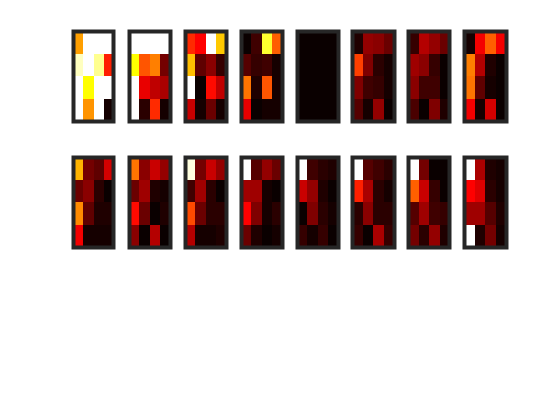




startPos1 = 1;
endPos1 = length(allThresholds{1});

figure

ctrPlot = 0;

for tctr = startPos1:1:endPos1
   
    TransMat = allTransMat{1}{tctr};
    TransMatStd = allTransMatStd{1}{tctr};
    
    %Recompute diffmat to the refernce point
    diffMat = sqrt((real(TransMat) - refTransMat).^2) ./ refTransMatStd;
    
    myFrobDist1(1,tctr) = sqrt(sum(sum((real(TransMat) - refTransMat).^2)));

    
    %Display the results
    ctrPlot = ctrPlot + 1;
    subplot(3,8,ctrPlot);
    
    
    imagesc(diffMat)
    caxis([0 3])
    colormap(hot)
    %colorbar
    set(gca,'FontSize',36)
    set(gca,'LineWidth',3)
    set(gca,'xtick',[]);
    set(gca,'ytick',[]);
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
   
end

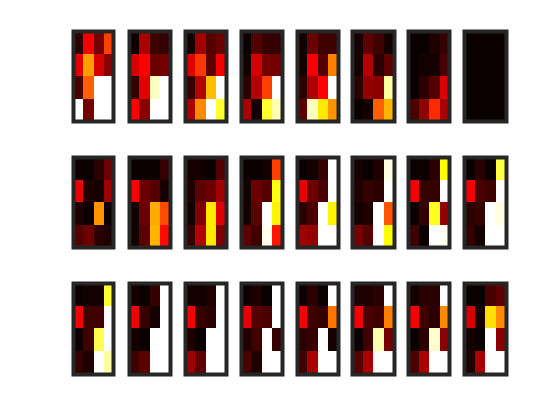


%PU1

refTransMat1 = real(allTransMat{2}{8});
refTransMatStd1 = real(allTransMatStd{2}{8});

startPos2 = 1;
endPos2 = length(allThresholds{2});

figure

ctrPlot = 0;

for tctr = startPos1:1:endPos2
  
    TransMat = allTransMat{2}{tctr};
    TransMatStd = allTransMatStd{2}{tctr};
    
    %Recompute diffmat to the refernce point
    diffMat = sqrt((real(TransMat) - refTransMat1).^2) ./ refTransMatStd1;
    
    myFrobDist2(1,tctr) = sqrt(sum(sum((real(TransMat) - refTransMat1).^2)));

    
    %Display the results
    ctrPlot = ctrPlot + 1;
    subplot(3,8,ctrPlot);
    
    
    imagesc(diffMat)
    caxis([0 3])
    colormap(hot)
    %colorbar
    set(gca,'FontSize',36)
    set(gca,'LineWidth',3)
    set(gca,'xtick',[]);
    set(gca,'ytick',[]);
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);

end

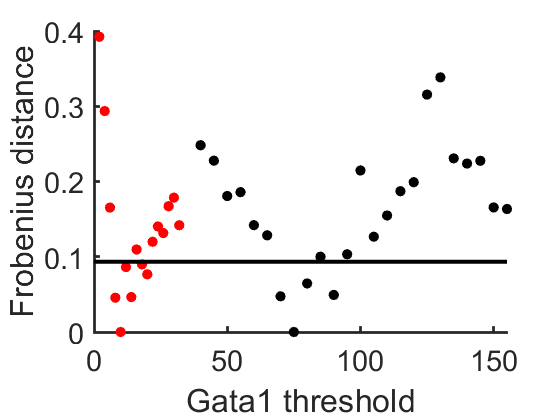


%FB plot
figure
scatter(allThresholds{1}(startPos1:1:endPos1),myFrobDist1(1,startPos1:1:endPos1),60,'ro','filled')
hold on
scatter(allThresholds{2}(startPos2:1:endPos2),myFrobDist2(1,startPos2:1:endPos2),60,'ko','filled')
set(gca,'FontSize',22)
set(gca,'LineWidth',2)
hold on
line([0 300] , [BgdAveFD BgdAveFD] , 'LineStyle' , '-' , 'Color' , 'k' , 'LineWidth' , 3)
xlim([0 max(allThresholds{2})])
 

xlabel('Gata1 threshold','FontSize',32 )
ylabel('Frobenius distance','FontSize',32 )